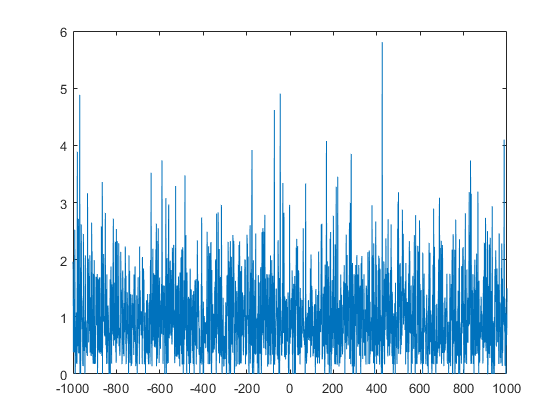

g2 = [];
for i = 1:4   
    tempni = []; tempnk = [];
    pattern = g2pat(i);
    x = 21;y = 17;    tau_range = 1000;
    ni = reshape(Image.photon(x+pattern(1,1),y+pattern(2,1),:),1,[]);
    nk = reshape(Image.photon(x+pattern(3,1),y+pattern(4,1),:),1,[]);

    tau_min = -tau_range;tau_max = tau_range;
    %% 计算 aveni, avenk
    aveni = mean(ni);
    avenk = mean(nk);
    %% 计算 sum(ni(t) * nk(t + tau))
    tempnk = repmat(nk,(tau_max - tau_min + 1),1);
    m = size(tempnk,1);
    tempnk = [tempnk';zeros(m)];
    tempnk = reshape(tempnk(1:end-m),[],m)';
    tempni = zeros(length(tempnk),1);
    tempni(tau_range:length(ni) + tau_range-1) = ni;
    sumnink = sum(tempni'.*tempnk,2);
    l = length(ni);
    l_nink = [[l-tau_range:1:l],[l-1:-1:l- tau_range]];
    avenink = sumnink./l_nink';
    %% 计算 g2trace
    g2(:,i) = avenink/(aveni * avenk);
%     plot([-tau_range:tau_range],g2(:,i))
%     hold on
end
    plot([-tau_range:tau_range],mean(g2,2))
    hold off

a2 = [];
for i = 1:4   
    tempni = []; tempnk = [];
    pattern = g2pat(i);
    x = 15;y = 17;    tau_range = 100;
    ni = reshape(Image.photon(x+pattern(1,1),y+pattern(2,1),:),1,[]);
    nk = reshape(Image.photon(x+pattern(3,1),y+pattern(4,1),:),1,[]);

    tau_min = -tau_range;tau_max = tau_range;
    %% 计算 aveni, avenk
    aveni = mean(ni);
    avenk = mean(nk);
    %% 计算 sum(ni(t) * nk(t + tau))
    tempnk = repmat(nk,(tau_max - tau_min + 1),1);
    m = size(tempnk,1);
    tempnk = [tempnk';zeros(m)];
    tempnk = reshape(tempnk(1:end-m),[],m)';
    tempni = zeros(length(tempnk),1);
    tempni(tau_range:length(ni) + tau_range-1) = ni;
    sumnink = sum(tempni'.*tempnk,2);
    l = length(ni);
    l_nink = [[l-tau_range:1:l],[l-1:-1:l- tau_range]];
    avenink = sumnink./l_nink';
    %% 计算 g2trace
    g2(:,i) = avenink/(aveni * avenk);
%     plot([-tau_range:tau_range],g2(:,i))
%     hold on
end
    plot([-tau_range:tau_range],mean(g2,2))
    hold off

% for tau = -tau_range:tau_range    
%         for t = 1:length(ni)
%             nink(tau_range + tau + 1,t) = ni(tau_range + tau + 1) * nk(tau_range + tau + 1 + t);
%         end
%     sumnink = sum(nink,2);
%     g2_2 = sumnink/(aveni * avenk);
%     plot([-tau_range:tau_range],g2_2)
% end